Implementing the 2D barebones FDTD acoustic code

c0 = 1500;        %speed of sound in water (m/s)
SIZE = 50;       %size of each array
dt = 0.0001;     %temporal step size
dx = 1;          %spatial step size
rho = 997;       %density of water in kg/m^3
Sc = (c0*dt)/dx;  %courant number
maxTime = 0.04;       %max time for the simulation to run
colDimsD = [SIZE,SIZE] %dimensions of the water column

colDimsD =     50    50


srcPosD = [SIZE/2,SIZE/2]  %source position in node coords

srcPosD =     25    25


%recPosD = [srcPosD(1),srcPosD(2)+2] %receiver position in node coords
recPosD = [10,10]

recPosD =     10    10


Pr = zeros(SIZE,SIZE);%pressure matrix
vx = zeros(SIZE,SIZE);%x-velocity matrix
vy = zeros(SIZE,SIZE);%y-velocity matrix
maxN = maxTime/dt;    %total number of frames
backscatter = zeros(maxN,1); % Array to store backscatter data

%Material properties
rhoMat = ones(SIZE,SIZE)*rho %density matrix initialised to water

rhoMat =    997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997
   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997
   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997   997
   997   997   997   997   997   997   997   997   997   997   997   997   997   997   9

%crMat = ones(SIZE,SIZE) %relative sound speed matrix
caMat = ones(SIZE,SIZE)*c0 %sound speed matrix initialised to water

caMat =         1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500
        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500        1500       

%cr <= 1, where 1 means sound speed is equal to the background speed c0
%sound speed = ca = cr*c0

%Setting up Aluminium box
%boxPosD = [recPosD(1),recPosD(2)+3] %left side of box (closest to the receiver)
%rhoMat(boxPosD(1)-4:(boxPosD(1)),boxPosD(2):(boxPosD(2)+4))=2700 %density of aluminium kg/m3
%caMat(boxPosD(1)-4:(boxPosD(1)),boxPosD(2):(boxPosD(2)+4))=6420 %sound speed in aluminium m/s
%rhoMat(boxPosD(1),boxPosD(2))=2700
%caMat(boxPosD(1),boxPosD(2))=6420
rhoMat(:,35)=7750; %density of steel
caMat(:,35)=5000; %sound speed of steel



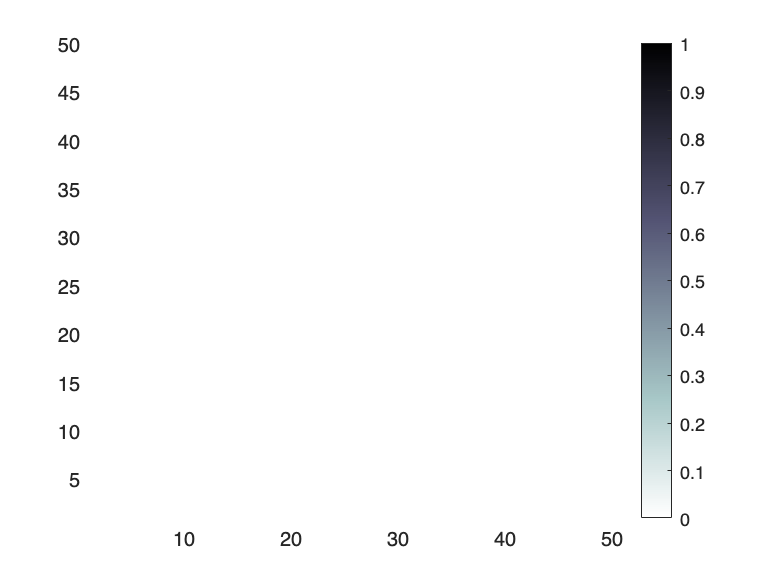

maxc = 1.0;
pl = abs(Pr(:,:)); %absolute value of pressure
h2 = pcolor(pl); 
colormap(flipud(bone));
colorbar;
caxis([0 maxc]);
xlim([1 SIZE]);
ylim([1 SIZE]);
shading interp;

%Source
fc = 0.075;     % Cutoff frequency (normalised 0.5=nyquist)
n0 = 30;        % Initial delay (samples)
sigma=sqrt(2*log(2))/(2*pi*(fc/dt)); %flow resistivity
n=0:maxN;
srcFn=exp(-dt^2*(n-n0).^2/(2*sigma^2));
srcFn=filter([1 -1], [1 -0.995], srcFn); % DC Blocker

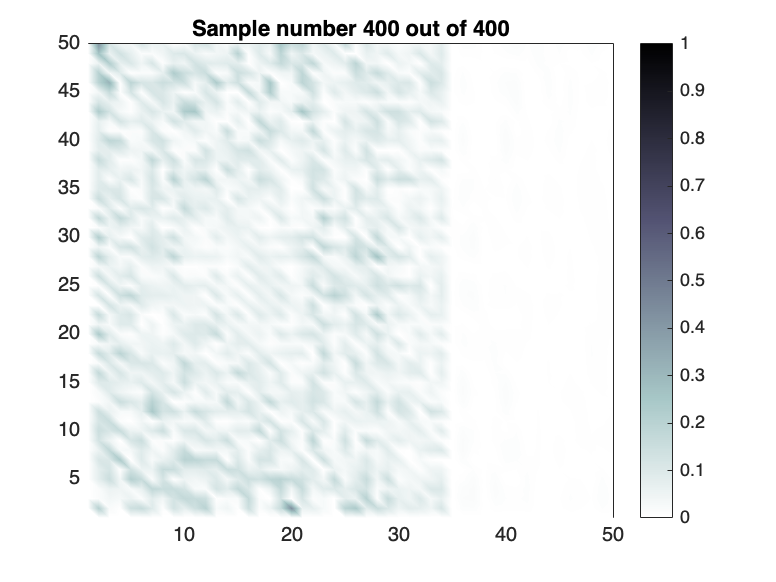


for count=1:maxN
    time = count*dt; %convert counter to time value
    for mm=1:SIZE-1
        %temp variable to store value in previous time step
        vx_old = vx(mm,:);
        %update x-velocity
        vx(mm,:) = vx_old - (2.*Sc./(c0*(rhoMat(mm,:)+rhoMat(mm+1,:)))).*(Pr(mm+1,:)-Pr(mm,:));
    end
    for nn=1:SIZE-1
        %temp variable to store value in previous time step
        vy_old = vy(:,nn);
        %update y-velocity
        vy(:,nn) = vy_old - (2.*Sc./(c0*(rhoMat(:,nn)+rhoMat(:,nn+1)))).*(Pr(:,nn+1)-Pr(:,nn));
    end
    for mm=2:SIZE
        for nn=2:SIZE
            %temp variable to store value in previous time step
            Pr_old = Pr(mm,nn);
            %update pressure
            %Pr(mm,nn) = Pr_old - (c0*Sc.*rhoMat(mm,nn).*(crMat(mm,nn)).^2).*(vx(mm,nn)-vx(mm-1,nn)...
                %+vy(mm,nn)-vy(mm,nn-1));
            Pr(mm,nn) = Pr_old - (rhoMat(mm,nn).*(caMat(mm,nn)).^2 *(dt/dx)).*(vx(mm,nn)...
                -vx(mm-1,nn) + vy(mm,nn)-vy(mm,nn-1));
        end
    end
    %hardwire a source node
    %vx(SIZE/2,SIZE/2) = 1/(100*(time+1));
    Pr(SIZE/2,SIZE/2) = Pr(srcPosD(1),srcPosD(2)) + srcFn(count);
    backscatter(mm) = Pr(recPosD(1),recPosD(2));
    pl = abs(Pr(:,:));
    set(h2,'CData',pl);
    title(sprintf('Sample number %d out of %d',count,maxN));
    drawnow;
end

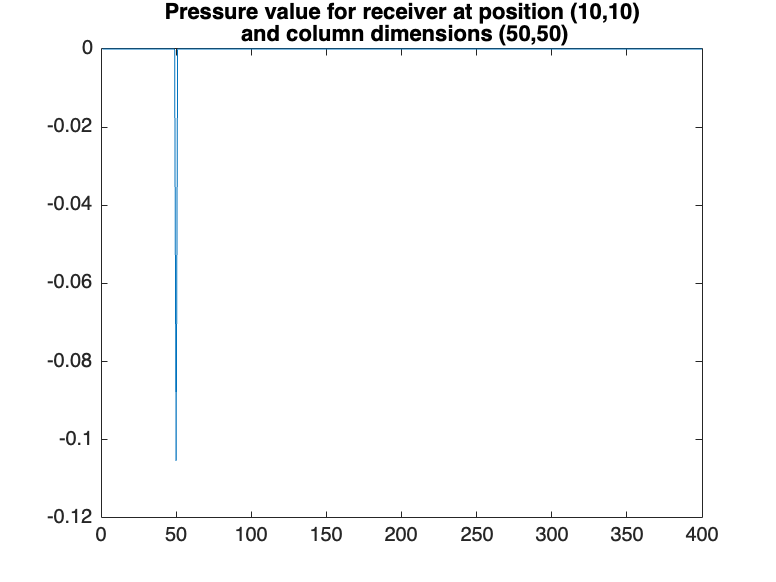

plot(backscatter)
title({ ...
    ['Pressure value for receiver at position (' num2str(recPosD(1)) ',' num2str(recPosD(2)) ')'] ...
    [' and column dimensions (' num2str(colDimsD(1)) ',' num2str(colDimsD(2)) ')'] ...
    })